
load('C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\occupancy_map_data4.mat')
map = Map

map =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     1
     1     0     0     0  

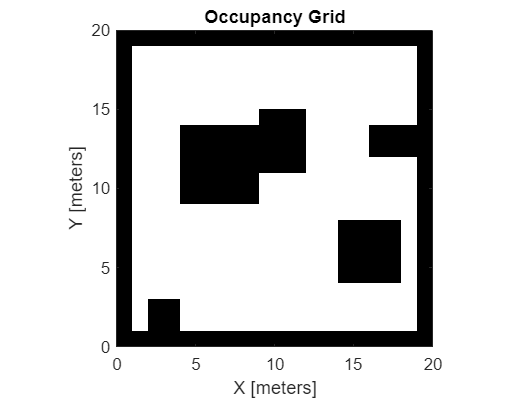

load ("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\occupancy_map4.mat")
oMap = occupancyMap(omap);
show(omap)

map

map =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     1
     1     0     0     0  

GW = createGridWorld(size(map,1),size(map,2), "Kings")

GW =   GridWorld with properties:

                GridSize: [20 20]
            CurrentState: "[1,1]"
                  States: [400×1 string]
                 Actions: [8×1 string]
                       T: [400×400×8 double]
                       R: [400×400×8 double]
          ObstacleStates: [0×1 string]
          TerminalStates: [0×1 string]
    ProbabilityTolerance: 8.8818e-16



ObstacleData = []


ObstacleData =

     []




for i = 1:size(map,1)
    for j = 1:size(map,2)
        if map(i, j) == 1
            obstacle = ["["+ num2str(i)+","+ num2str(j)+"]"];
            ObstacleData = [ObstacleData; obstacle];
        end    
    end
end


GW.ObstacleStates = ObstacleData;
GW.CurrentState = '[8,5]';


for i=1:size(GW.States,1)
    if GW.States(i) == GW.CurrentState
        startState = i;
    end
end


GW.TerminalStates = '[17,17]';

%updateStateTranstionForObstacles(GW);
nS = numel(GW.States);
nA = numel(GW.Actions);

GW.R = -1*ones(nS,nS,nA);
GW.R(:,state2idx(GW,GW.ObstacleStates),:) = -50

GW =   GridWorld with properties:

                GridSize: [20 20]
            CurrentState: "[8,5]"
                  States: [400×1 string]
                 Actions: [8×1 string]
                       T: [400×400×8 double]
                       R: [400×400×8 double]
          ObstacleStates: [139×1 string]
          TerminalStates: "[17,17]"
    ProbabilityTolerance: 8.8818e-16


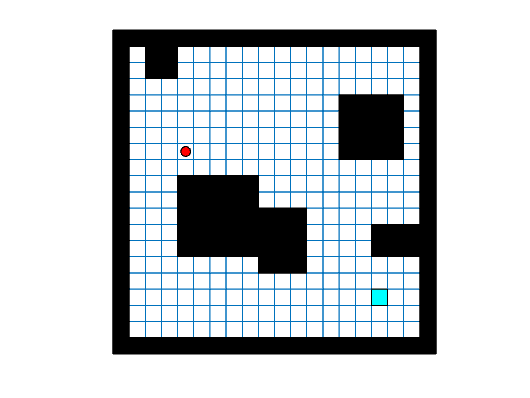

GW.R(:,state2idx(GW,GW.TerminalStates),:) = 10;
env = rlMDPEnv(GW);
plot(env)

env.ResetFcn = @() startState; %Itt be kell állítani, hogy melyik a kezdő állapot
%rng(0)

qTable = rlTable(getObservationInfo(env), ...
    getActionInfo(env));

qFcnAppx = rlQValueFunction(qTable, ...
    getObservationInfo(env), ...
    getActionInfo(env));

qAgent = rlQAgent(qFcnAppx);
qAgent.AgentOptions.EpsilonGreedyExploration.Epsilon = .4;
qAgent.AgentOptions.CriticOptimizerOptions.LearnRate = 0.1;


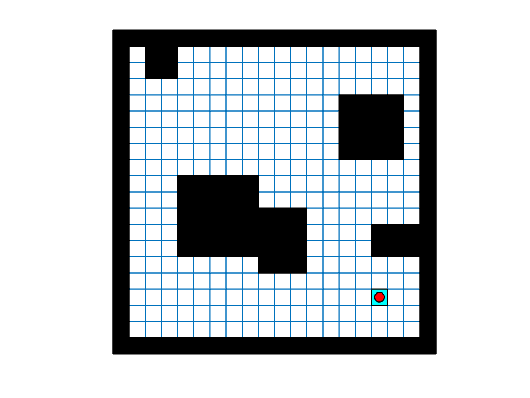

trainOpts = rlTrainingOptions;
trainOpts.MaxStepsPerEpisode = 500;
trainOpts.MaxEpisodes= 200;
trainOpts.StopTrainingCriteria = "AverageReward";
trainOpts.StopTrainingValue = 1000;
trainOpts.ScoreAveragingWindowLength = 30;


trainingStats = train(qAgent,env,trainOpts);

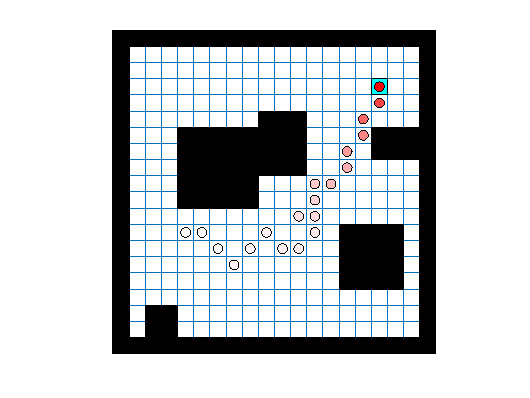


plot(env)
set(gca, 'YDir','reverse')
env.Model.Viewer.ShowTrace = true;
env.Model.Viewer.clearTrace;
exp = sim(qAgent,env);

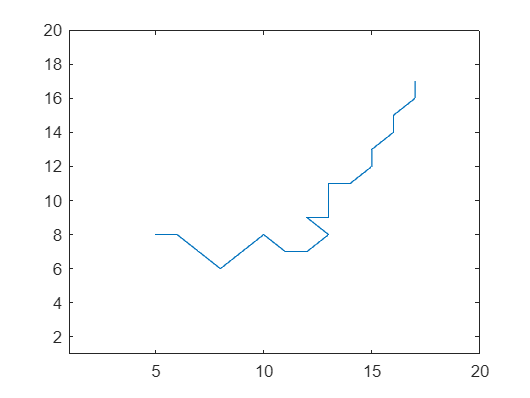



x = [];
y = [];

for i = 1:size(exp.Observation.MDPObservations.Data,3)
    data = exp.Observation.MDPObservations.Data(i);
    state = env.Model.States(data);
    matrix = str2num(state);
    x = [x;matrix(:,2)];
    y = [y;matrix(:,1)];
end

figure
plot(x,y)
axis([1 20 1 20])


%Meg kell csinálni a teljes Dubins smoothing connection-őket

dubConnObj = dubinsConnection;
dubConnObj.MinTurningRadius = 0.1

dubConnObj =   dubinsConnection with properties:

    DisabledPathTypes: {}
     MinTurningRadius: 0.1000
         AllPathTypes: {'LSL'  'LSR'  'RSL'  'RSR'  'RLR'  'LRL'}


allPose = [];

size(x,1);
startange = 0;

for i=1:size(x,1)-1
    tavolsag_x = x(i+1) - x(i);
    tavolsag_y = y(i+1) - y(i);

    degree = atan2d(tavolsag_y,tavolsag_x);
    R = deg2rad(degree);

    startData = [x(i) y(i) startange];
    enddata = [x(i+1) y(i+1) R];
    startange = R;
    [pathSegObj,pathCosts] = connect(dubConnObj,startData,enddata);
    length = pathSegObj{1}.Length;
    poses = interpolate(pathSegObj{1},0:0.05:length);

    allPose = [allPose; [poses(:,1), poses(:,2)]];
end



allPose

allPose =     5.0000    8.0000
    5.0500    8.0000
    5.1000    8.0000
    5.1500    8.0000
    5.2000    8.0000
    5.2500    8.0000
    5.3000    8.0000
    5.3500    8.0000
    5.4000    8.0000
    5.4500    8.0000


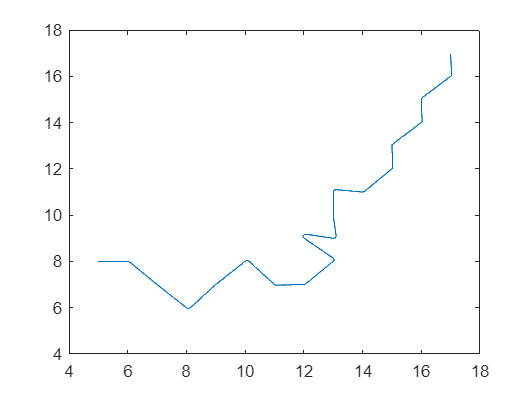

plot(allPose(:,1), allPose(:,2))

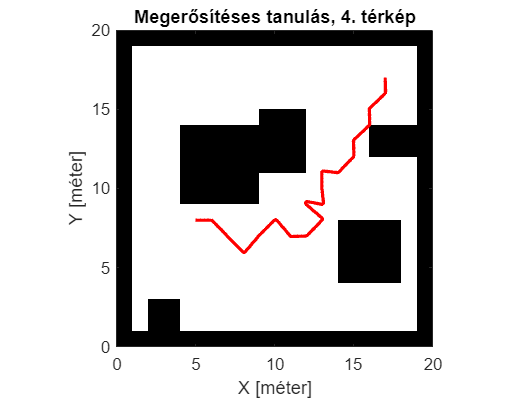


figure
show(oMap)
hold on
plot(allPose(:,1),allPose(:,2),'r-','LineWidth',2)
xlabel("X [méter]")
ylabel("Y [méter]")
title("Megerősítéses tanulás, 4. térkép")

%plot(pathObj.States(:,1),pathObj.States(:,2),'b-','LineWidth',2)
%plot(allVFHdata(:,1),allVFHdata(:,2),'y-','LineWidth',2)
